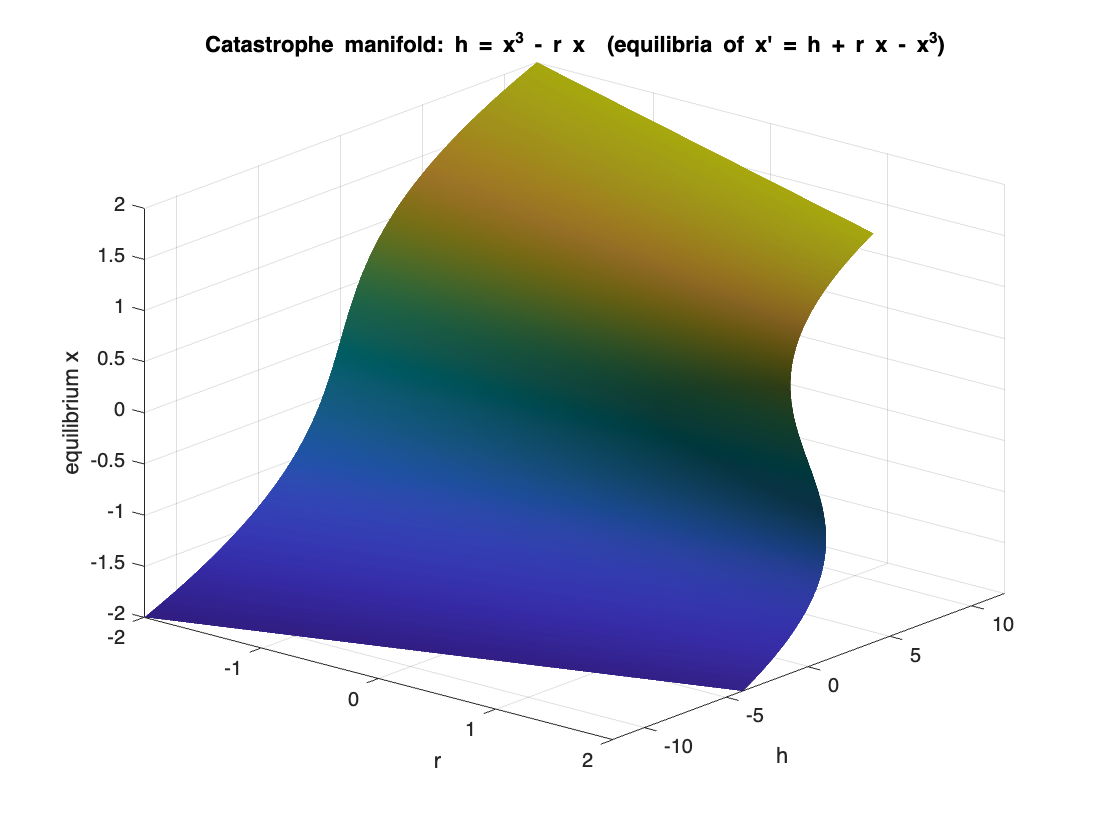

%% ================================================================
%  6) Codimension-2 cusp/catastrophe: x' = h + r x - x^3
%     Equilibria satisfy: h = x^3 - r x  (catastrophe manifold)
%     Fold (saddle-node) occurs where f=0 and f_x=0:
%       h + r x - x^3 = 0,   r - 3x^2 = 0
%     => r = 3x^2, h = -2x^3, giving cusp curve: 27 h^2 = 4 r^3 (r>=0)
% ================================================================

% --- (a) Plot catastrophe manifold surface h = x^3 - r x in (r,h,x)
rVals = linspace(-2, 2, 200);
xVals = linspace(-2, 2, 200);
[R,X] = meshgrid(rVals, xVals);
H = X.^3 - R.*X;

figure('Name','Cusp catastrophe manifold','Color','w');
surf(R, H, X, 'EdgeColor','none'); 
xlabel('r'); ylabel('h'); zlabel('equilibrium x');
title('Catastrophe manifold: h = x^3 - r x  (equilibria of x'' = h + r x - x^3)');
view(40,25); camlight; lighting gouraud;
grid on;

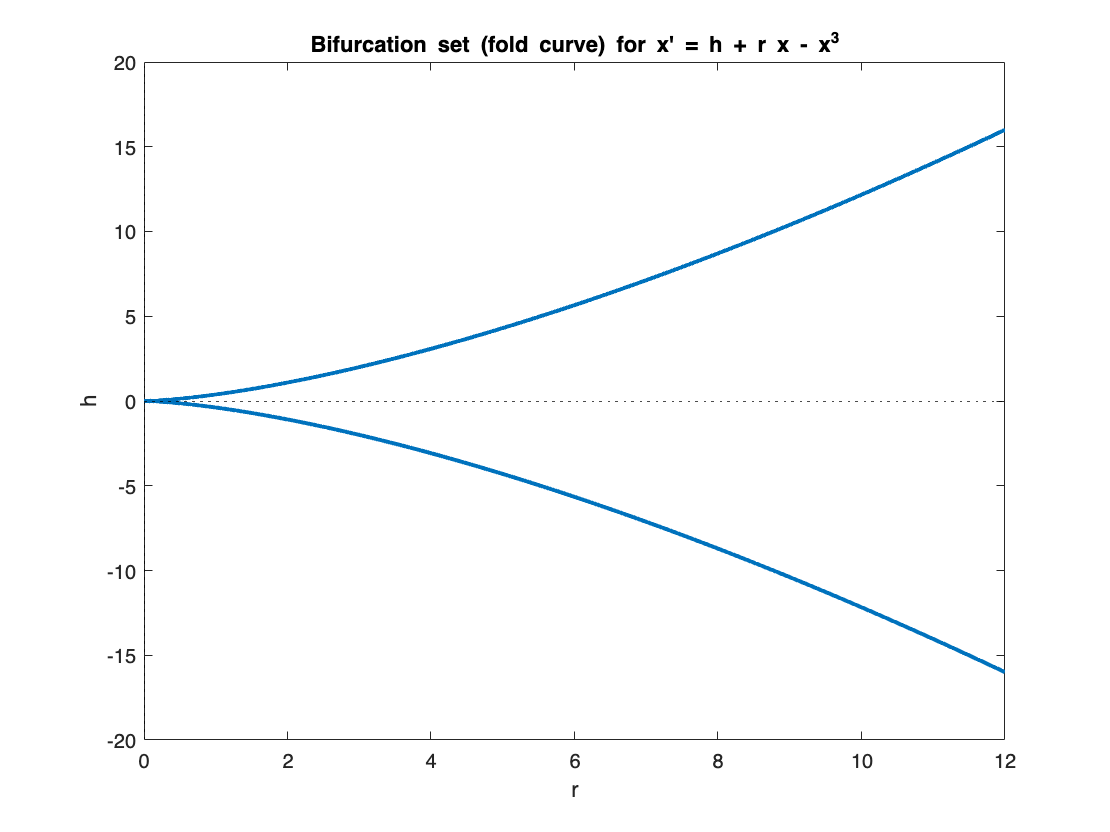


% [Insert teaching moment]
% For fixed (r,h), equilibria correspond to intersections of a vertical line
% with this surface. Inside the cusp region: 3 intersections (3 equilibria).
% Outside: 1 intersection.

% --- (b) Plot cusp (fold) curve in (r,h) plane
s = linspace(-2,2,2000);        % parameter = x at fold
r_fold = 3*s.^2;
h_fold = -2*s.^3;

figure('Name','Cusp curve (bifurcation set) in (r,h)','Color','w'); hold on; box on;
plot(r_fold, h_fold,'LineWidth',2);
xlabel('r'); ylabel('h');
title('Bifurcation set (fold curve) for x'' = h + r x - x^3');
% Also show the symmetric cusp formula explicitly as reference:
% 27 h^2 = 4 r^3, r>=0.
xline(0,'k:'); yline(0,'k:');

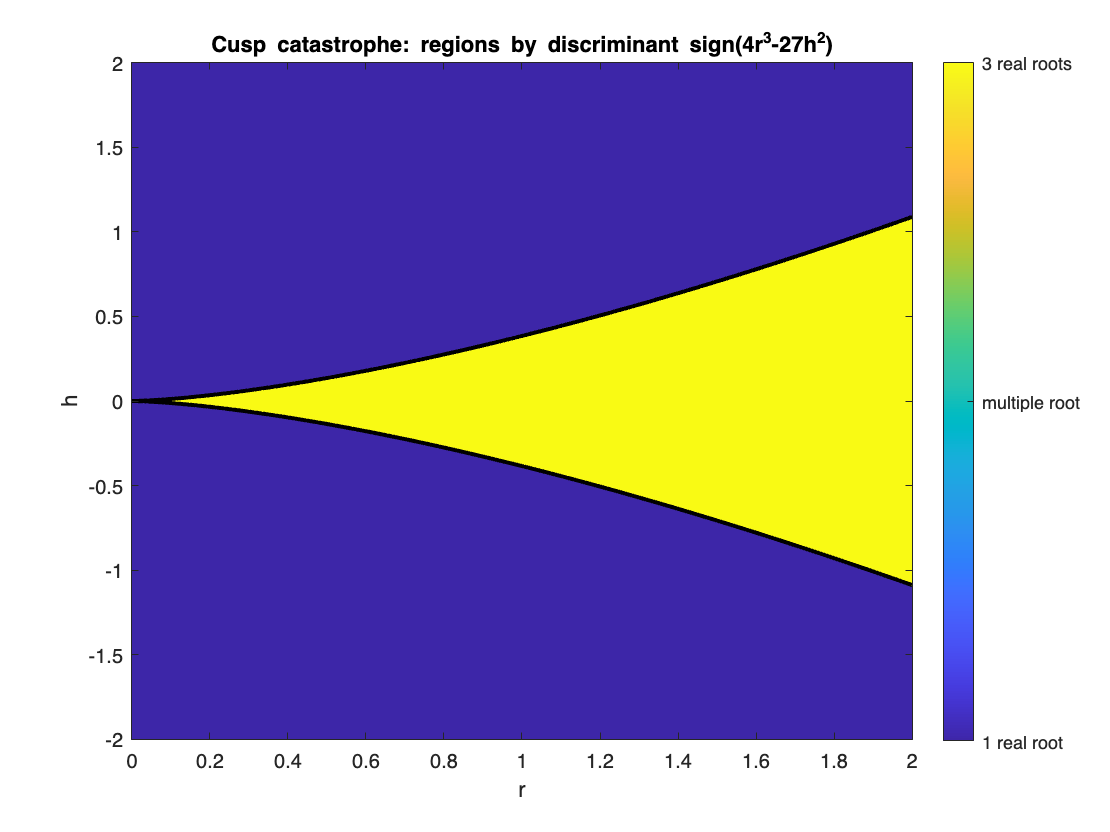


% --- (c) Show number of equilibria on a grid (inside vs outside cusp)
% Use discriminant: for x^3 - r x - h = 0, discriminant Δ = 4 r^3 - 27 h^2.
% If Δ > 0: 3 distinct real roots; Δ = 0: multiple root; Δ < 0: 1 real root.
rGrid = linspace(0,2,400);   % cusp lives at r>=0
hGrid = linspace(-2,2,400);
[RR,HH] = meshgrid(rGrid,hGrid);
Delta = 4*RR.^3 - 27*HH.^2;

figure('Name','Cusp regions: number of real equilibria','Color','w');
imagesc(rGrid, hGrid, sign(Delta)); axis xy; colormap(parula);
colorbar('Ticks',[-1 0 1],'TickLabels',{'1 real root','multiple root','3 real roots'});
xlabel('r'); ylabel('h');
title('Cusp catastrophe: regions by discriminant sign(4r^3-27h^2)');
hold on;
% overlay fold curves using explicit formula h = +/- 2 (r/3)^{3/2}
rPlot = linspace(0,2,600);
hUpper =  2*(rPlot/3).^(3/2);
hLower = -2*(rPlot/3).^(3/2);
plot(rPlot, hUpper,'k','LineWidth',2);
plot(rPlot, hLower,'k','LineWidth',2);